% Caso k2=0
clc
Wn2 = 1e4/47;
Wn = sqrt(Wn2);

numT = Wn2;
denT = [1 0 Wn2];

T = tf(numT,denT)

T =
 
     212.8
  -----------
  s^2 + 212.8
 
Continuous-time transfer function.



% Solo ponemos la matriz A
f = @(t,X) [X(2); -Wn2*X(1)]

f = function_handle with value:
    @(t,X)[X(2);-Wn2*X(1)]


x1 = linspace(-.5,.5,10);
x2 = linspace(-5,5,10);

[x,y] = meshgrid(x1,x2);

u = zeros(size(x));
v = zeros(size(x));

t=0;
for i=1:numel(x)
    Xprime = f(t,[x(i),y(i)]);
    u(i) = Xprime(1);
    v(i) = Xprime(2);
end

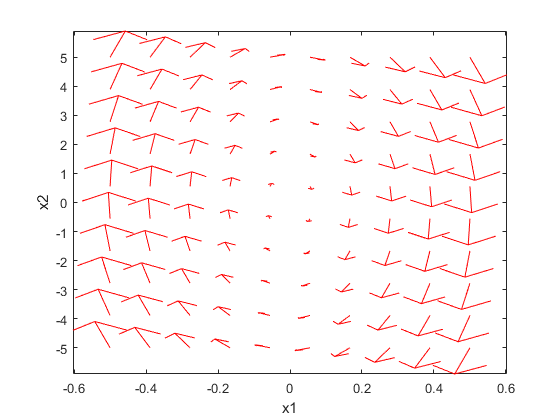

quiver(x,y,u,v,'r'); figure(gcf)
xlabel('x1')
ylabel('x2')
ylim([-5 5])
xlim([-.5 .5])
axis tight;

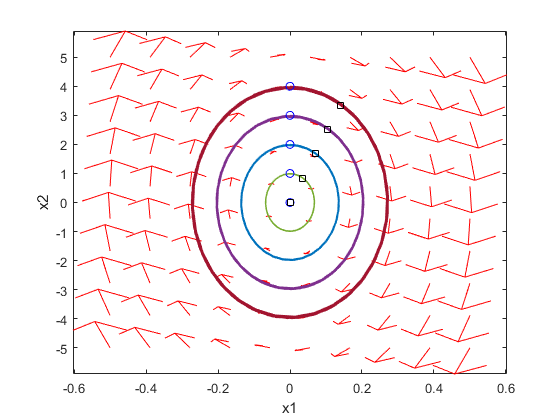

hold on
for x20 = [0 1 2 3 4]
    [ts,ys] = ode45(f,[0,50],[0;x20]);
    plot(ys(:,1),ys(:,2))
    plot(ys(1,1),ys(1,2),'bo') % starting point
    plot(ys(end,1),ys(end,2),'ks') % ending point
end
hold off